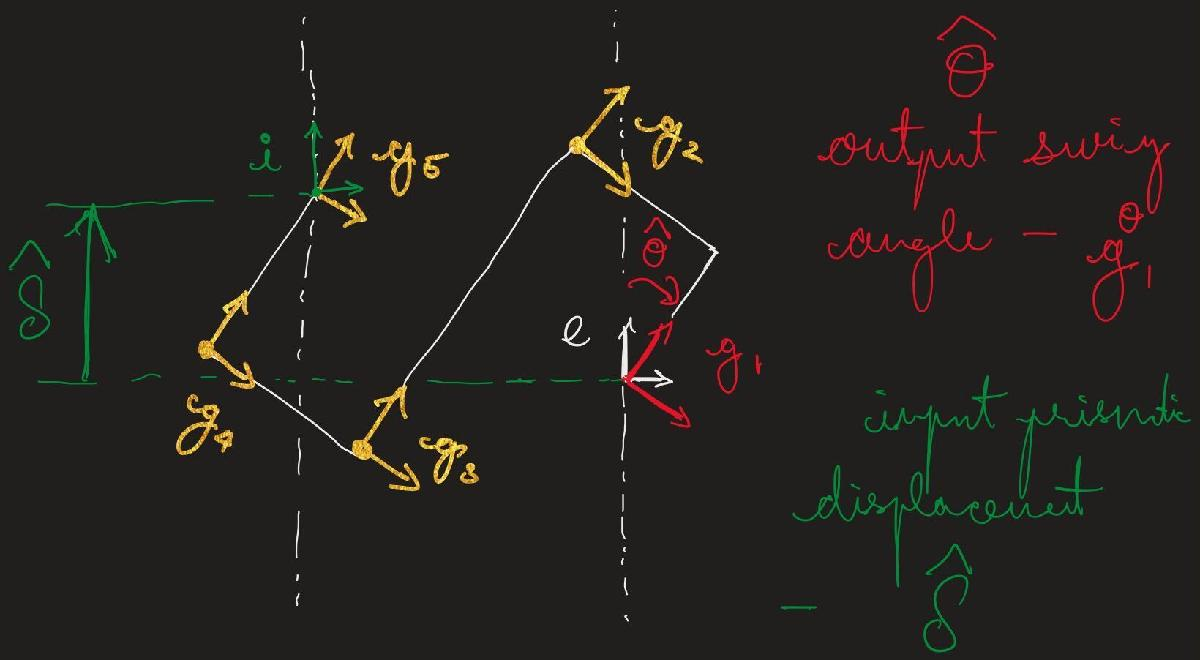

## $SE(2)$ functions and transforms

syms x y theta u v beta real

v2M_SE2 = @(v) [cos(v(3)), -sin(v(3)), v(1);
                sin(v(3)),  cos(v(3)), v(2);
                        0,         0,    1];

M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);

L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); 

T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g);

g_vec = [x;
         y;
         theta];
h_vec = [u;
         v;
         beta];

g_mat = v2M_SE2(g_vec);

T_g_to_T_hg = T_gL_h(g_vec, h_vec);
T_g_to_T_gh = T_gR_h(g_vec, h_vec);

gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat);

TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)]));
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta]));
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10);

theta_circ = [0,0,1]'; x_circ = [1,0,0]'; y_circ = [0,1,0]';
theta_sel = [0,0,1]'; x_sel = [1,0,0]'; y_sel = [0,1,0]';

## DASH Swing Kinematics

syms l positive real
syms theta_hat real
h_e__1 = [0, 0, theta_hat]'; % define the transforms as column SE(2) vectors
h_1__2 = [-l, l, 0]';
h_2__3 = [0, -2*l, 0]';
h_3__4 = [-l, 0, 0]';
h_4__5 = [0, l, 0]';
h_5__i = [0, 0, -theta_hat]';

% Now that we have each transform, we can build up the full transform to
% the input frame.
h_e__i = M2v_SE2(v2M_SE2(h_e__1)*v2M_SE2(h_1__2)*v2M_SE2(h_2__3)*v2M_SE2(h_3__4)*...
    v2M_SE2(h_4__5)*v2M_SE2(h_5__i))

$$h\_e\_\_i = \left(\begin{array}{c} -2\,l\,\cos\left(\hat{\theta }\right)\\ -2\,l\,\sin\left(\hat{\theta }\right)\\ 0 \end{array}\right)$$

% Hence, the prismatic input from the motor:
delta_hat = dot(y_sel, h_e__i)

$$delta\_hat = -2\,l\,\sin\left(\hat{\theta }\right)$$